# Train Fully Convex Neural Network for Image Classification

This example shows how to create a fully input convex neural network and train it on CIFAR-10 data. This example uses fully connected based convex networks, rather than the more typical convolutional networks, proven to give higher accuracy on the training and test data set. The aim of this example is to demonstrate the expressive capabilities convex constrained networks have by classifying natural images and demonstrating high accuracies on the training set. Further discussion on the expressive capabilities of convex networks for tasks including image classification can be found in [1]. 

## Prepare Data

Download the CIFAR-10 data set [1]. The data set contains 60,000 images. Each image is 32-by-32 pixels in size and has three color channels (RGB). The size of the data set is 175 MB. Depending on your internet connection, the download process can take time.

datadir = "."; 
downloadCIFARData(datadir);

Load the CIFAR-10 training and test images as 4-D arrays. The training set contains 50,000 images and the test set contains 10,000 images. Use the CIFAR-10 test images for network validation.

[XTrain,TTrain,XTest,TTest] = loadCIFARData(datadir);

For illustration in this example, subsample this data set evenly in each class. You can increase the number of samples by moving the slider to smaller values.

subSampleFrequency = 10;
XTrain = XTrain(:,:,:,1:subSampleFrequency:end);
XTest = XTest(:,:,:,1:subSampleFrequency:end);
TTrain = TTrain(1:subSampleFrequency:end);
TTest = TTest(1:subSampleFrequency:end);

You can display a random sample of the training images using the following code.

## Define FICNN Network Architecture

Use the `buildConstrainedNetwork` function to create a fully input convex neural network suitable for this data set.

- The CIFAR-10 images are 32-by-32 pixels. Therefore, create a fully convex network specifying the `inputSize=[32 32 3]`.

- Specify a vector a hidden unit sizes of decreasing value in `numHiddenUnits`. The final number of outputs of the network must be equal to the number of classes, which in this example is 10.

inputSize = [32 32 3];
numHiddenUnits = [512 128 32 10];

Seed the network initialization for reproducibility.

rng(0);
ficnnet = buildConstrainedNetwork("fully-convex",inputSize,numHiddenUnits)

ficnnet =   dlnetwork with properties:

         Layers: [15×1 nnet.cnn.layer.Layer]
    Connections: [17×2 table]
     Learnables: [14×3 table]
          State: [0×3 table]
     InputNames: {'image_input'}
    OutputNames: {'add_4'}
    Initialized: 1

  View summary with summary.


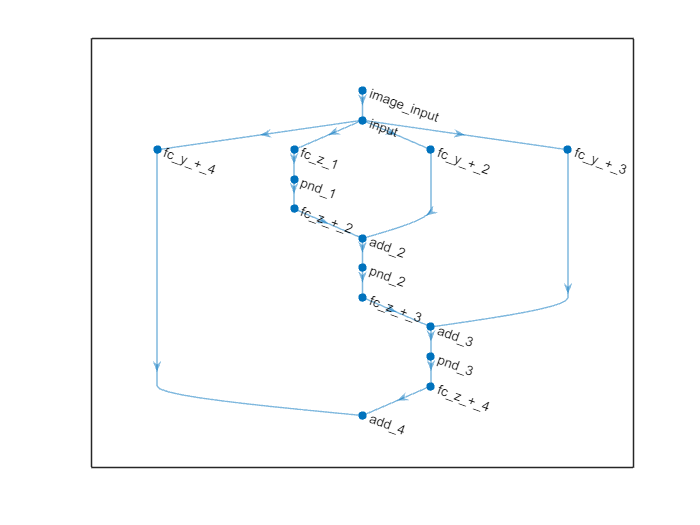

plot(ficnnet)

## Specify Training Options

Train for a specified number of epochs with a mini-batch size of 256. To attain high training accuracy, you may need to train for a larger number of epochs, for example `numEpochs=8000`, which could take several hours.

numEpochs = 8000;
miniBatchSize = 256;
initialLearnRate = 0.1;
decay = 0.005;
lossMetric = "crossentropy";

Create a `minibatchqueue` object that processes and manages mini-batches of images during training. For each mini-batch:

- Use the custom mini-batch preprocessing function `preprocessMiniBatch` (defined at the end of this example) to convert the labels to one-hot encoded variables.

- Format the image data with the dimension labels `"SSCB"` (spatial, spatial, channel, batch). By default, the `minibatchqueue` object converts the data to `dlarray` objects with underlying type `single`.

- Discard partial mini-batches.

- Train on a GPU if one is available. By default, the `minibatchqueue` object converts each output to a `gpuArray` if a GPU is available. Using a GPU requires Parallel Computing Toolbox™ and a supported GPU device. For information on supported devices, see [GPU Support by Release](docid:distcomp_ug#mw_57e04559-0b60-42d5-ad55-e77ec5f5865f).

xds = arrayDatastore(XTrain,IterationDimension=4);
tds = arrayDatastore(TTrain,IterationDimension=1);
cds = combine(xds,tds);
mbqTrain = minibatchqueue(cds,...
    MiniBatchSize=miniBatchSize,...
    MiniBatchFcn=@preprocessMiniBatch,...
    MiniBatchFormat=["SSCB" ""], ...
    PartialMiniBatch="discard");

## Train Network

Use the `trainConstrainedNetwork` to train the fully input convex network, using the training options in the previous section. Note that the "`crossentropy`" loss in the `trainConstrainedNetwork` applies a softmax operation to the convex network outputs first, before computing the cross-entropy. This is because adding a `softmaxLayer` operation to the network does not preserve convexity, so the softmax is incorporated into the network loss instead.

Note the training can take several minutes to several hours to complete, depending on the choice of `numEpochs`.

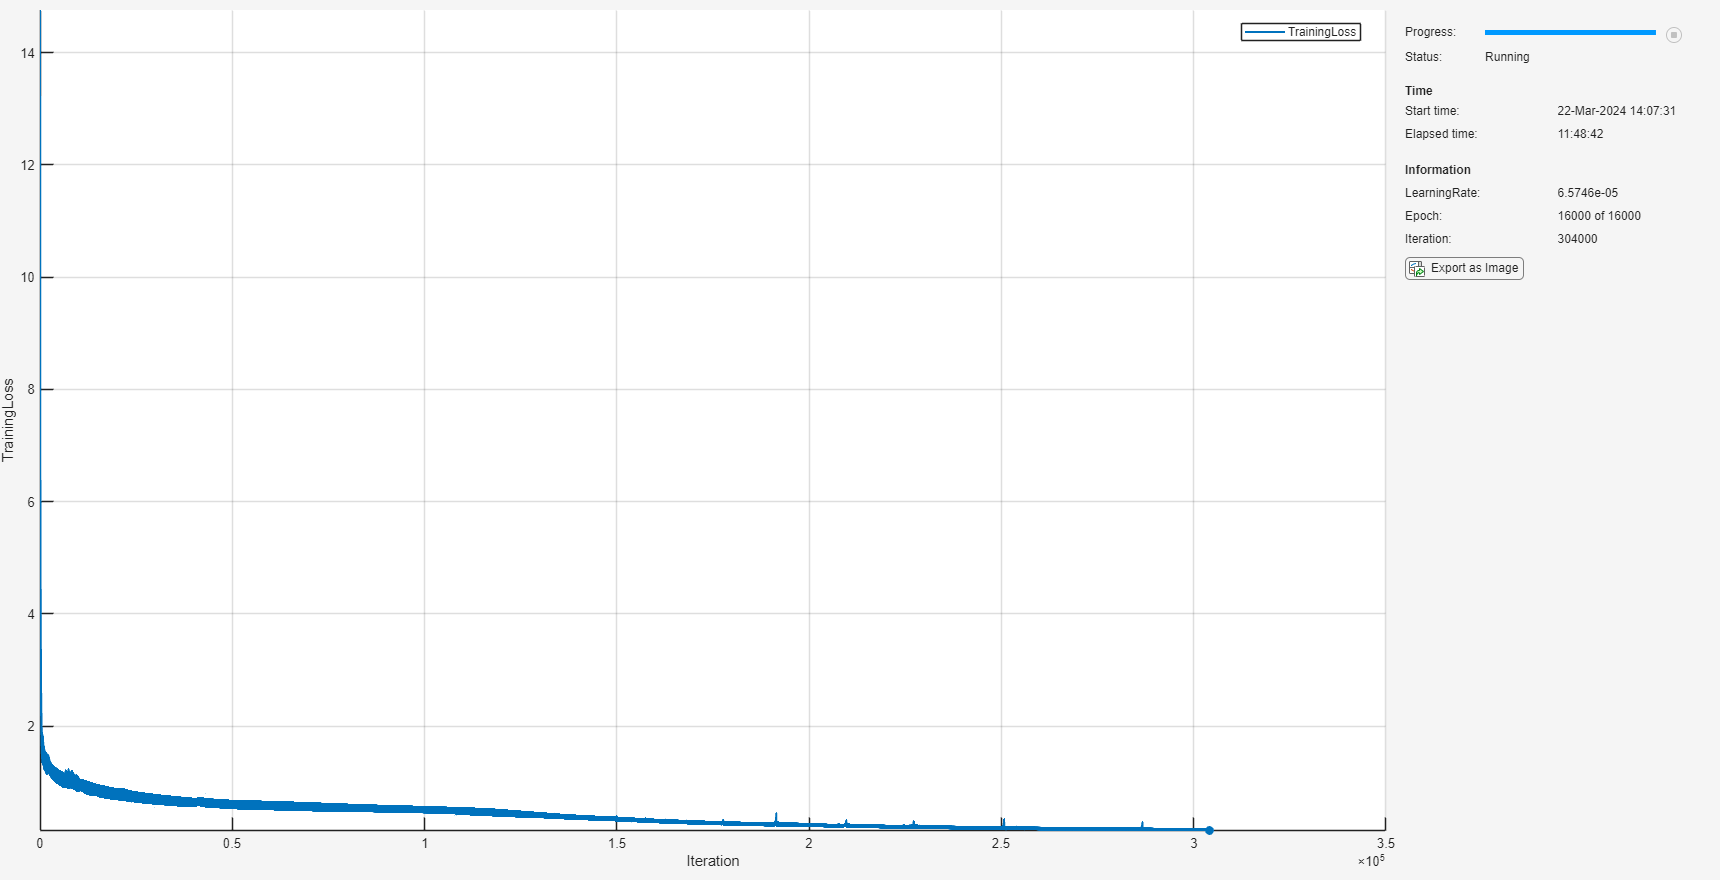

trained_ficnnet = trainConstrainedNetwork("fully-convex",ficnnet,mbqTrain,...
    MaxEpochs=numEpochs,...
    InitialLearnRate=initialLearnRate,...
    Decay=decay,...
    LossMetric=lossMetric,...
    ShuffleMinibatches=false,...
    TrainingMonitorLogScale=false);

## Evaluate Trained Network

Calculate the final accuracy of the network on the training set and test set. To make predictions with multiple observations, use the `minibatchpredict` function. First create a `minibatchqueue` for the test data set.

xds = arrayDatastore(XTest,IterationDimension=4);
tds = arrayDatastore(TTest,IterationDimension=1);
cds = combine(xds,tds);
mbqTest = minibatchqueue(cds,...
    MiniBatchSize=miniBatchSize,...
    MiniBatchFcn=@preprocessMiniBatch,...
    MiniBatchFormat=["SSCB" ""], ...
    PartialMiniBatch="discard");

Next, use the `minibatchpredict` function to compute the network outputs. To convert the prediction scores to labels, use the `scores2label` function as well as apply the `softmax `function to the output of the convex network. The `minibatchpredict` function automatically uses a GPU if one is available. Using a GPU requires a Parallel Computing Toolbox™ license and a supported GPU device. For information on supported devices, see [GPU Computing Requirements](docid:distcomp_ug.mw_57e04559-0b60-42d5-ad55-e77ec5f5865f). Otherwise, the function uses the CPU.

As the `PartialMiniBatch` is set to "`discard`", and so the final minibatch may be incomplete. Therefore, discard the same values from `TTrain` to enable computation of accuracy.

scores = minibatchpredict(trained_ficnnet,mbqTrain);
YTrainPred = scores2label(softmax(scores),categories(TTrain));
trainError = mean(YTrainPred' ~= TTrain(1:size(scores,2)));
disp("Training accuracy: " + (1-trainError)*100 + "%")

Training accuracy: 97.7364%


Compute the accuracy on the test set.

scores = minibatchpredict(trained_ficnnet,mbqTest);
YTestPred = scores2label(softmax(scores),categories(TTest));
testError = mean(YTestPred' ~= TTest(1:size(scores,2)));
disp("Test accuracy: " + (1-testError)*100 + "%")

Test accuracy: 31.5848%


The networks output has been constrained to be convex in every pixel in every colour. Even with this level of restriction, the network is able to fit reasonably well to the training data. You can see poor accuracy on the test data set but, as discussed at the start of the example, it is not anticipated that such a fully input convex network comprising of fully connected operations should generalize well to natural image classification.

Plot the confusion matrix for the training set. Display the precision and recall for each class by using column and row summaries.

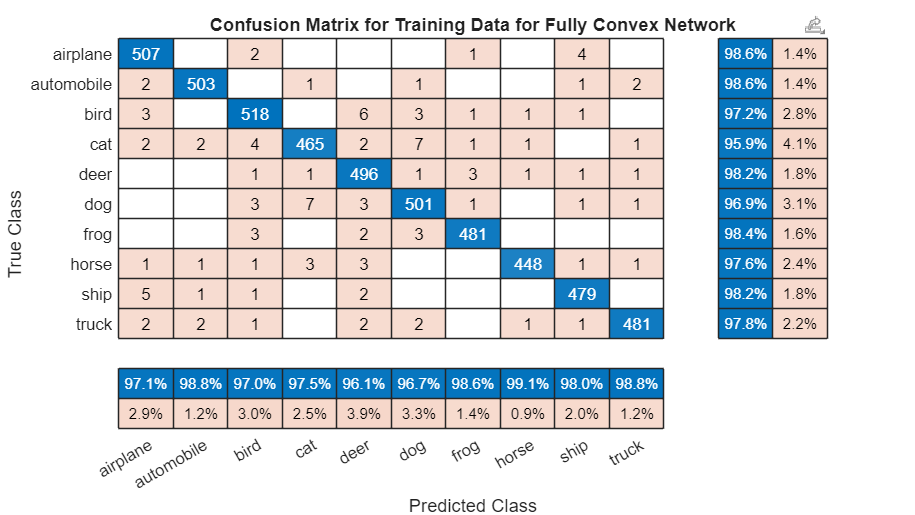

figure(Units="normalized",Position=[0.2 0.2 0.4 0.4]);
cm = confusionchart(TTrain(1:numel(YTrainPred)),YTrainPred');
cm.Title = "Confusion Matrix for Training Data for Fully Convex Network";
cm.ColumnSummary = "column-normalized";
cm.RowSummary = "row-normalized";

To summarise, the fully input convex network is able to fit to the training data set, which is labelled natural images. The training can take a considerable amount of time owing to the weight projection to the constrained set after each gradient update, which slows down training convergence. Nevertheless, this example illustrates the flexibility and expressivity convex neural networks have to correctly classifying natural images.

## Supporting Functions

### Mini Batch Preprocessing Function

The `preprocessMiniBatch` function preprocesses a mini-batch of predictors and labels using the following steps:

- Preprocess the images using the `preprocessMiniBatchPredictors` function.

- Extract the label data from the incoming cell array and concatenate into a categorical array along the second dimension.

- One-hot encode the categorical labels into numeric arrays. Encoding into the first dimension produces an encoded array that matches the shape of the network output.

function [X,T] = preprocessMiniBatch(dataX,dataT)

% Preprocess predictors.
X = preprocessMiniBatchPredictors(dataX);

% Extract label data from cell and concatenate.
T = cat(2,dataT{1:end});

% One-hot encode labels.
T = onehotencode(T,1);

end

### Mini-Batch Predictors Preprocessing Function

The `preprocessMiniBatchPredictors` function preprocesses a mini-batch of predictors by extracting the image data from the input cell array and concatenate into a numeric array. For grayscale input, concatenating over the fourth dimension adds a third dimension to each image, to use as a singleton channel dimension. You divide by 255 to normalize the pixels to `[0,1]` range.

function X = preprocessMiniBatchPredictors(dataX)
X = single(cat(4,dataX{1:end}))/255;
end

## References

[1] Amos, Brandon, et al. Input Convex Neural Networks. arXiv:1609.07152, arXiv, 14 June 2017. arXiv.org, https://doi.org/10.48550/arXiv.1609.07152.

*Copyright 2024 The MathWorks, Inc.*